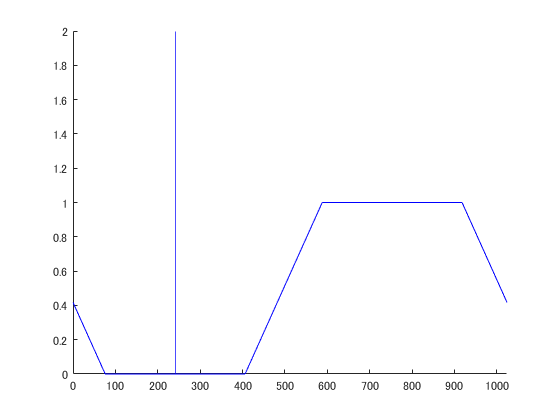

N = 1024;
X = linspace(0,N,1000);

i   = 241;
alpha = 182;

clip = @(x) min(1,max(0,x));
d = @(i,pos,N) min(N-max(i-pos,pos-i),max(i-pos,pos-i));
a = @(i,pos,N,alpha) clip((d(i,pos,N)-N/4)/alpha+0.5);

clf;
hold on
plot(X,a(i,X,N,alpha),"Color","b");xline(i,"Color","b")
xlim([-inf inf]);ylim([0,2]);